Frequency responce code:

DT_48_2_90 = desiredTorque

DT_48_2_90 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


OP_48_2_90 = torqueSensor

OP_48_2_90 = struct with fields:
         time: [100008×1 double]
      signals: [1×1 struct]
    blockName: 'ec90flat48V/To Workspace'


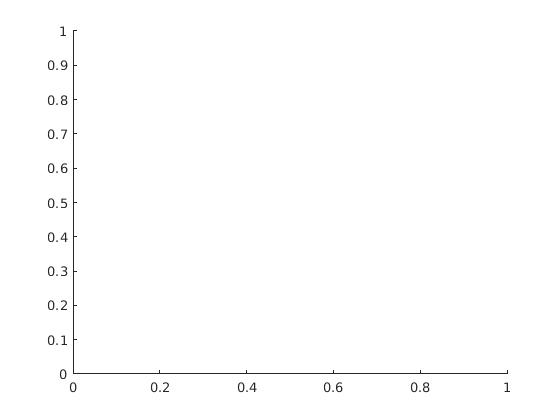

%gain_sum = cat(2, gain_sum, gain_48_2)
clf
hold on

plot(gain_sum(2:end,1), gain_sum(2:end,2))

The end operator must be used within an array index expression.

plot(gain_sum(2:end,1), gain_sum(2:end,3))
xlabel('Frequency')
ylabel('Gain')
title('Frequency Responce of EC90 Flat Motor');
leg = legend('5', '2');
title(leg, 'Desired Torque');
leg.Location = 'northeast';
hold off
clf

So dependent on how high the force required will mean if it is able to apact to a certain frequency.

Checking against EC60 and EC90 at 18V.

Will get a better responce nearing 


%save('freqResEC90_48_5and2')


First row, the amplitude

first column frequency 

gain_voltage_frequency

DT_voltage_frequency

if ampliftde not 5

DT_voltage_amp_frequency

Above was incorrect way to do this;

Need to normalise time from the signal first:

Run through a rate transition module in matlab

normalised

torque = normalisedTorque.signals.values

torque =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


time = normalisedTorque.time

time =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


For laplace need a function need to get how it varied over that change. 

curve fitting between the change should give it.

B = torque>0;

greater_0_torque = torque(B);
C = greater_0_torque < 0.99;
great_0_less_1_tor = greater_0_torque(C)

great_0_less_1_tor =     0.1170
    0.2210
    0.3127
    0.3936
    0.4649
    0.5280
    0.5836
    0.6326
    0.6759
    0.7141


topbit = size(great_0_less_1_tor)

topbit =     36     1


time_axis = 0:0.001:((topbit(1)-1)*0.001)

time_axis =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350


frequencyAxis = flip(time_axis.^-1)

frequencyAxis = 	1.0e+03 *

    0.0286    0.0294    0.0303    0.0312    0.0323    0.0333    0.0345    0.0357    0.0370    0.0385    0.0400    0.0417    0.0435    0.0455    0.0476    0.0500    0.0526    0.0556    0.0588    0.0625    0.0667    0.0714    0.0769    0.0833    0.0909    0.1000    0.1111    0.1250    0.1429    0.1667    0.2000    0.2500    0.3333    0.5000    1.0000       Inf


syms x
p2 = 0.003959;
p3 =-0.01229; 
p4 = 0.03692;
p5 = -0.086;
p6 = 0.1304;
p7 = 0.9015;
curveFitTorque = p1*x^6 + p2*x^5 + p3*x^4 + p4*x^3 + p5*x^2 + p6*x + p7;

y = laplace(curveFitTorque)

$$y = \frac{163\,\left(\frac{9015\,s}{1304}+1\right)}{1250\,s^{2}}-\frac{43}{250\,s^{3}}+\frac{2769}{12500\,s^{4}}-\frac{3687}{12500\,s^{5}}+\frac{68466243551077605}{144115188075855872\,s^{6}}-\frac{347564328464798505}{576460752303423488\,s^{7}}$$

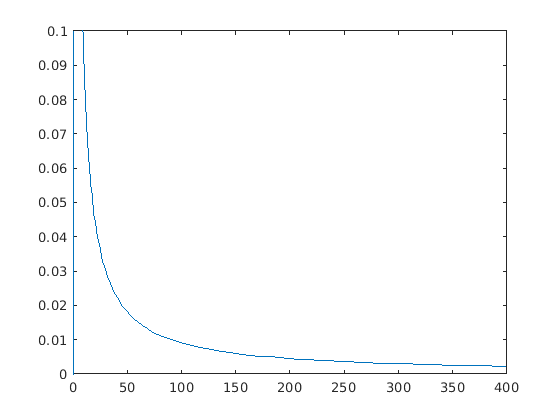


fplot(y,[0 1000])

xlim([0 400])
ylim([0 0.1])



frequency_torque = laplace(torque)

untitled fit 1	great_0_less_1_tor vs. time_axis	poly6	1.2964603537686758E-7	0.9999999348474624	29.0	0.999999921367627	6.686219368245344E-5	7.0			